clear
clc
close all

### Definition der Variablen

l = 1.5;
m = 5;
u = 4;
r = 0.06;
M = 0.2;
R = 1;
L = 0.0003;
psi = 0.09;
J = 7.2e-4;
g = 9.81;

### Definition der Übertrgungsfunktionen

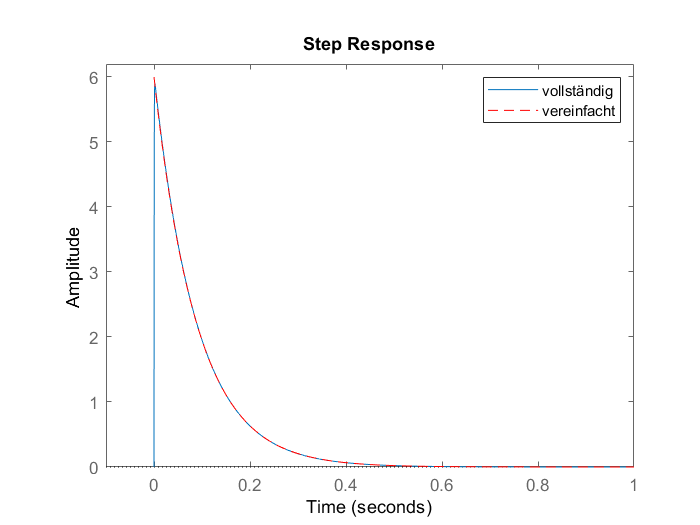

s = tf('s');

F = u/r*(J/psi)*s/...
    (1+J*R/(psi^2)*s+J*L/(psi^2)*s^2); %Vollständige Übertragungsfunktion des Stellglieds
Fe = u/r*(J/psi)*s/...
    (1+J*R/(psi^2)*s); %Vereinfachte Übertragungsfunktion des Stellglieds
% Vergleich der Reaktionen der vollständigen und vereinfachten
% Übertragungsfunktionen auf einen Einheitssprung
step(F)
hold on
step(Fe,"--r")
legend("vollständig","vereinfacht")
xlim([-.1 1])
ylim([0 6.2])

## c)

### Errechnen der gegbenen Parameter

a0 = (3*g*(M+m))/(l*(4+M+m));
b0 = 3/(l*(4*M+m));
a2 = 1;

bp = (3*g+m)/(4*M+m);
bf = (4/(4*M+m));

### Reglerbestimmung durch Polvorgabe

D = 0.7;
w0 = 9;

% Bestimmung der benötigten Pole
c3 = 1;
c2 = 3+2*D*w0;
c1 = 2*D*w0+w0^2;
c0 = 3*w0^2;

c = [c3 c2 c1 c0]';

% Aufstellen der Sylvestermatrix
A = [a2 0 0 0;...
    0 a2 0 0;...
    -a0 0 b0 0;...
    0 -a0 0 b0];

% Lösen des Gleichungssystems
k = A\c

k = 	1.0e+03 *

    0.0010
    0.0156
    0.3036
    1.2064



A1 = k(1);
A0 = k(2);
B1 = k(3);
B0 = k(4);

% Einführen der Laplace-Variable 
s = tf('s');

% Definition von F_phi,Fx als Übertragungsfunktion der Regelstrecke
Fs = b0/(s^2-a0);

% Definition der Reglerübertragungsfunktion
Fr = (B1*s+B0)/(A1*s+A0);

T_num = Fr*Fs/(1+Fr*Fs);
S_num = 1/(1+Fr*Fs);

T = minreal(T_num);
S = minreal(S_num);

% bode(T,S)
% legend("T","S")
% title("Verlauf der (komplementären) Sensitivitäsfunktion")

p0 = pi/180;

% Durchführen der Simulation
sim("Aufgabe2")

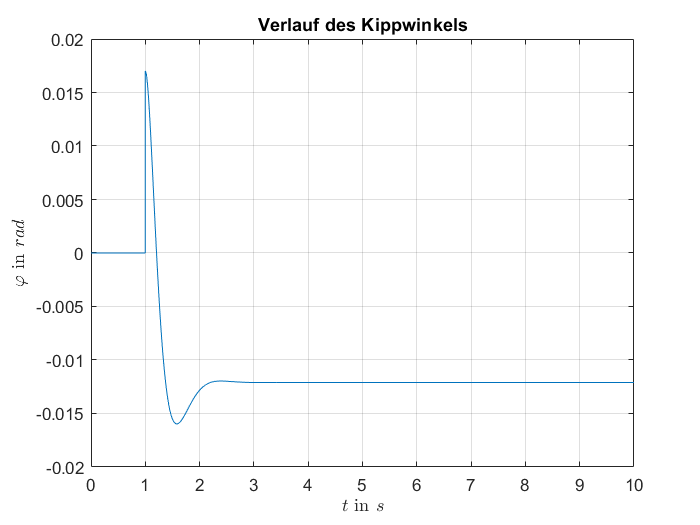


% Plotten des Verlaufs des Kippwinkels
figure()
plot(phi_b)
title("Verlauf des Kippwinkels")
xlabel("$t$ in $s$",'Interpreter','latex')
ylabel("$\varphi$  in  $rad$",'Interpreter','latex')
grid on

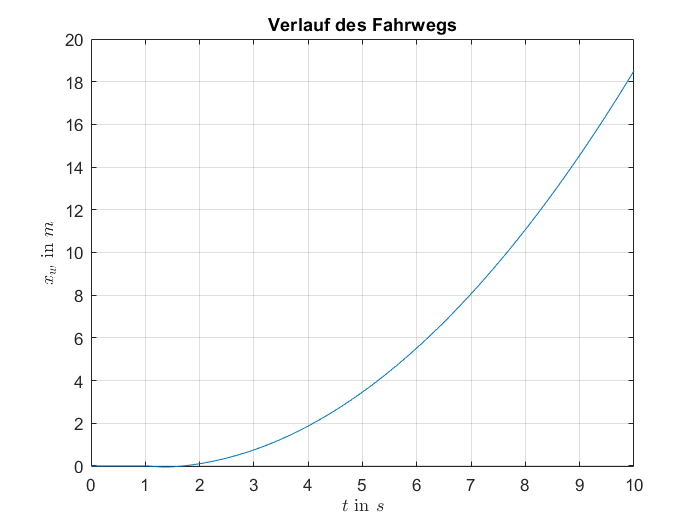

% Plotten des Verlaufs des Fahrwegs
figure()
plot(xw_b)
title("Verlauf des Fahrwegs")
xlabel("$t$ in $s$",'Interpreter','latex')
ylabel("$x_w$  in  $m$",'Interpreter','latex')
grid on

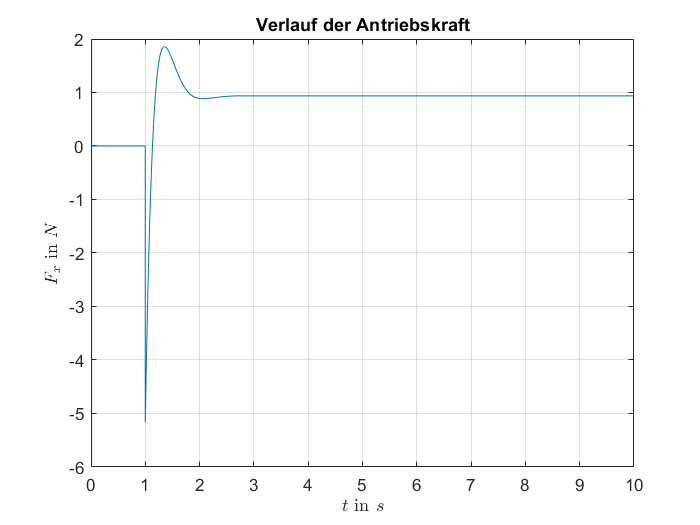

% Plotten des Verlaufs der Antriebskraft
figure()
plot(Fx_b)
title("Verlauf der Antriebskraft")
xlabel("$t$ in $s$",'Interpreter','latex')
ylabel("$F_x$  in  $N$",'Interpreter','latex')
grid on

## c)

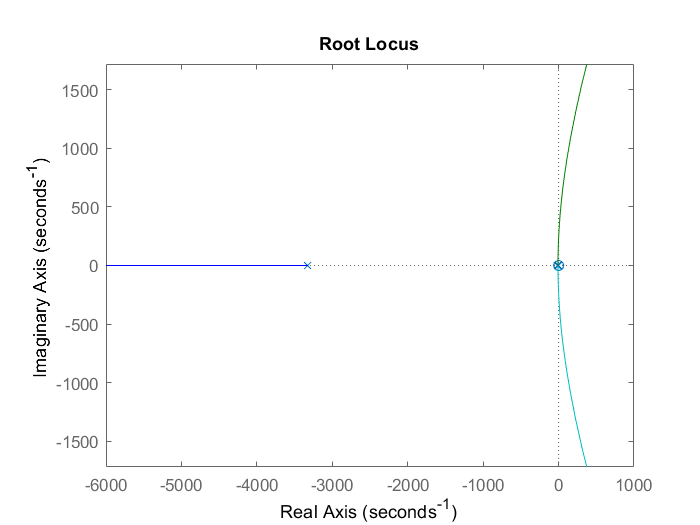

% Definition der geforderten Reglerfunktion (ohne Verstärkungsfaktor)
Fr2 = (s-3)/(s+1);

% Aufstellen des offenen Reglekreises
Lnum = Fr2*F*Fs;
L = minreal(Lnum);

% Plot der Wurzelortskurve des offenen Regelkreises
figure()
rlocus(Lnum)

ylim([-10 10])
axis equal

Select a point in the graphics window


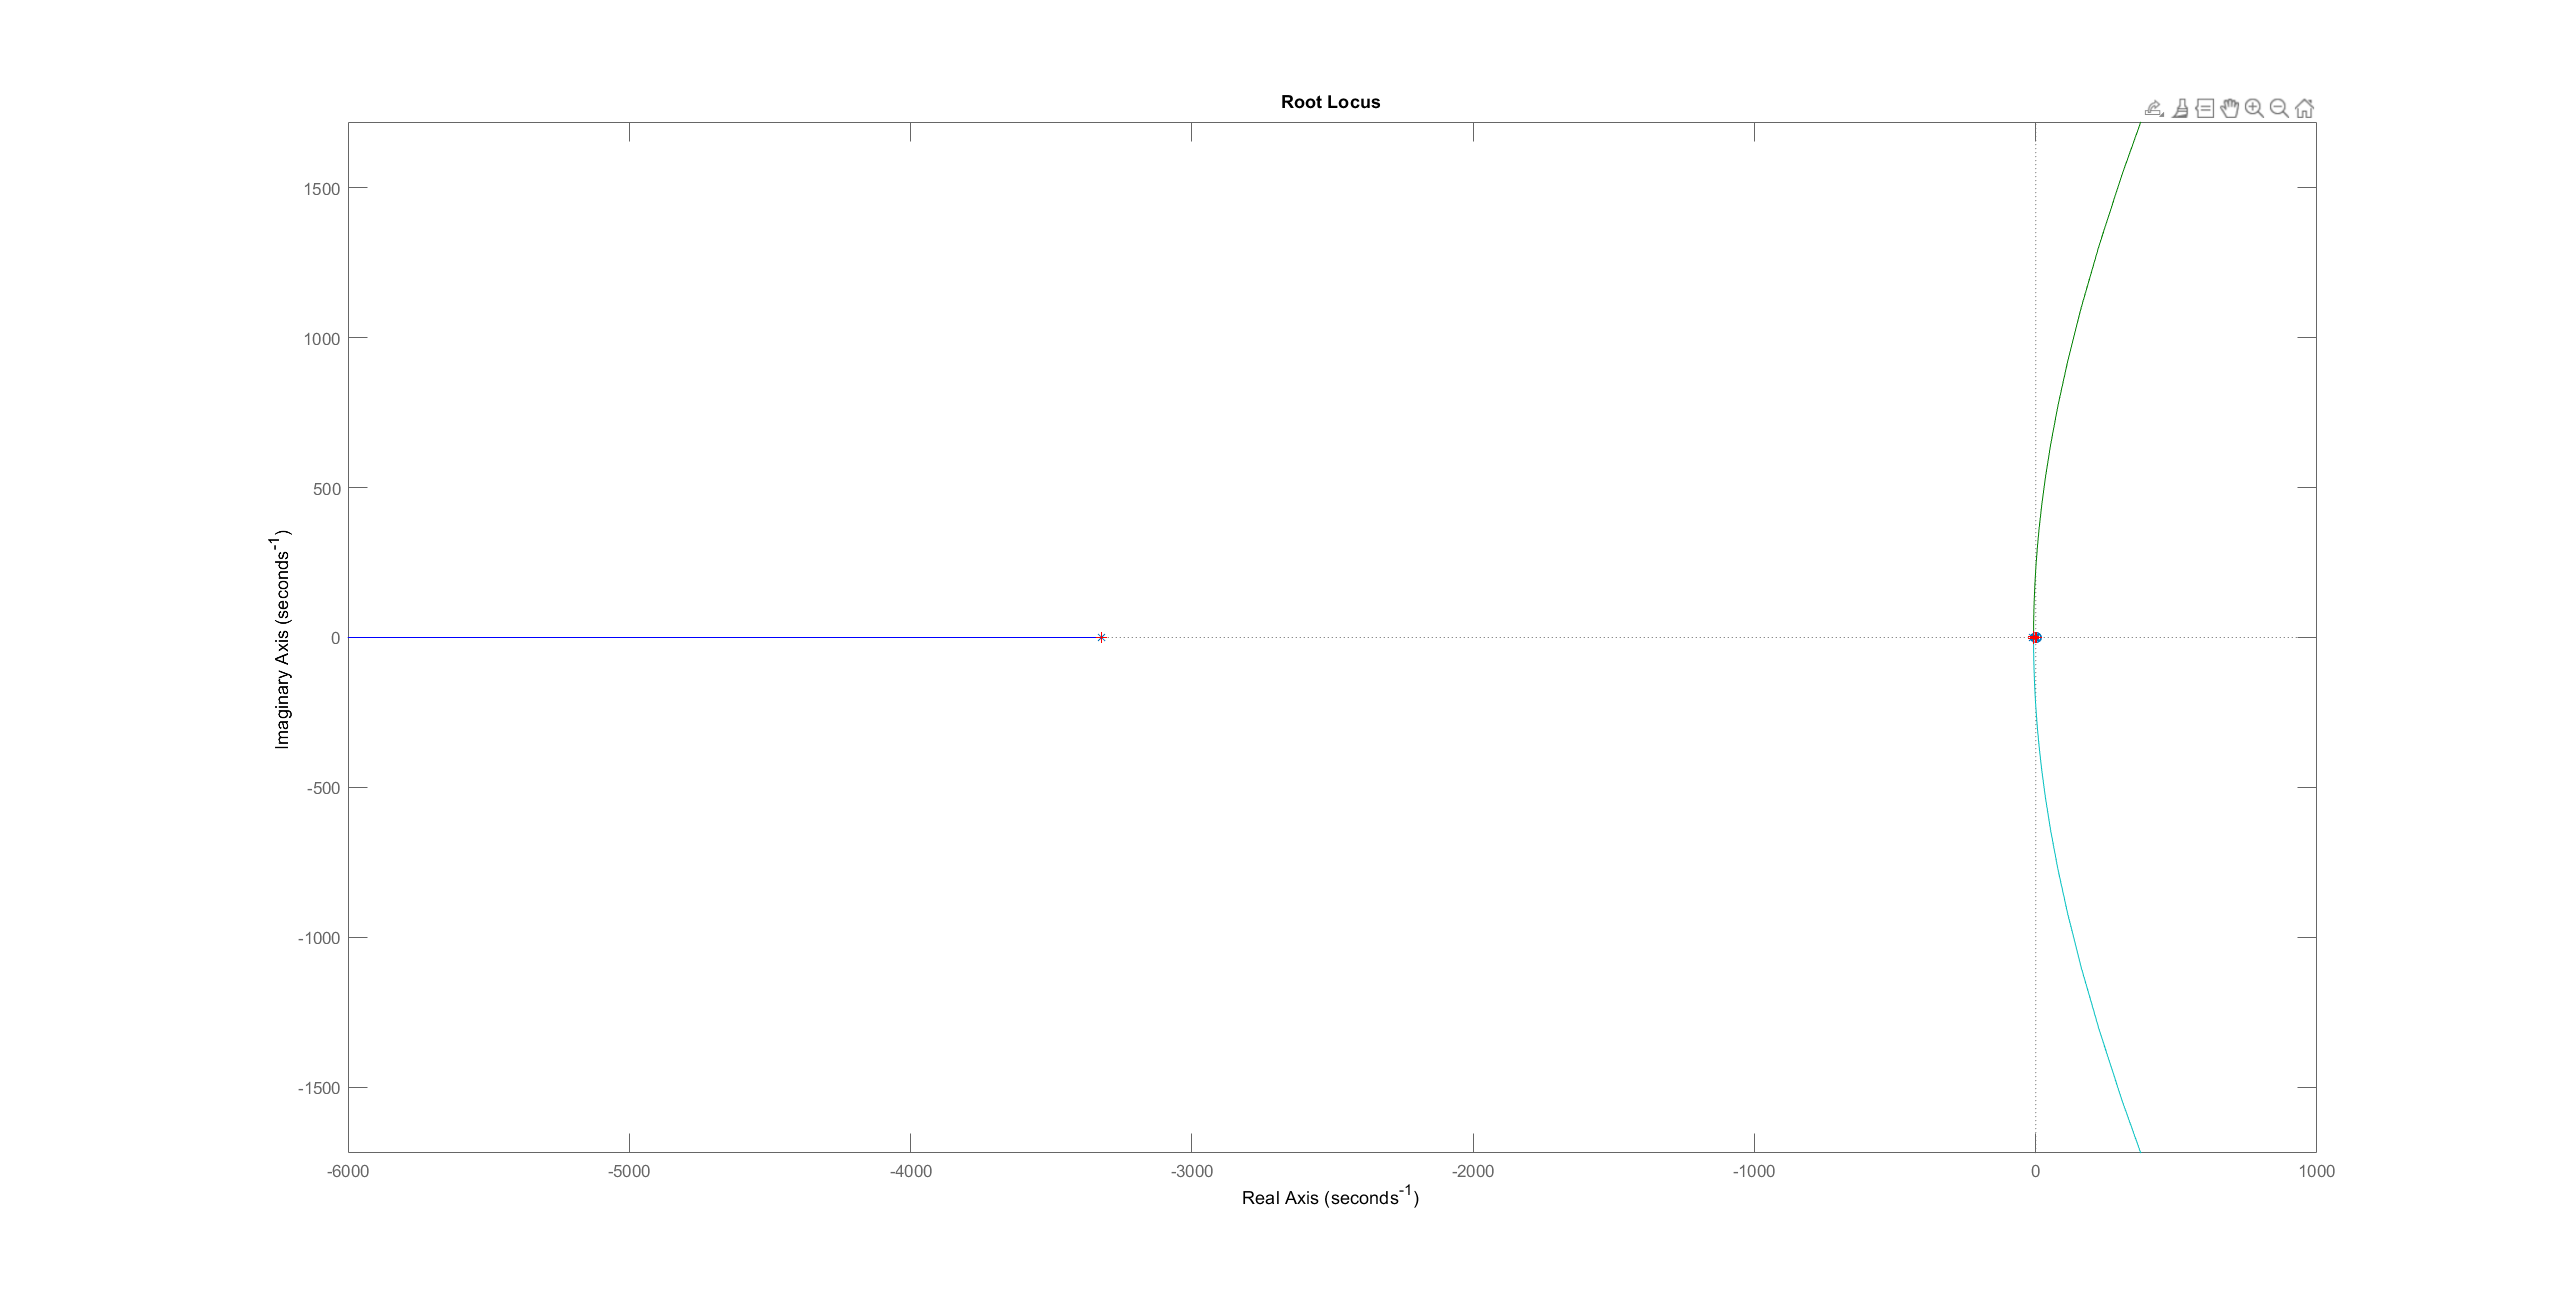

selected_point = -7.8720 - 3.3335i

k = 11.8668

poles = 	1.0e+03 *

  -3.3221 + 0.0000i
  -0.0075 + 0.0033i
  -0.0075 - 0.0033i
   0.0033 + 0.0000i
  -0.0006 + 0.0000i



% Tool zum Ermitteln des Verstärkungsfaktors aus der Wurzelortskurve
[k,poles]=rlocfind(L)

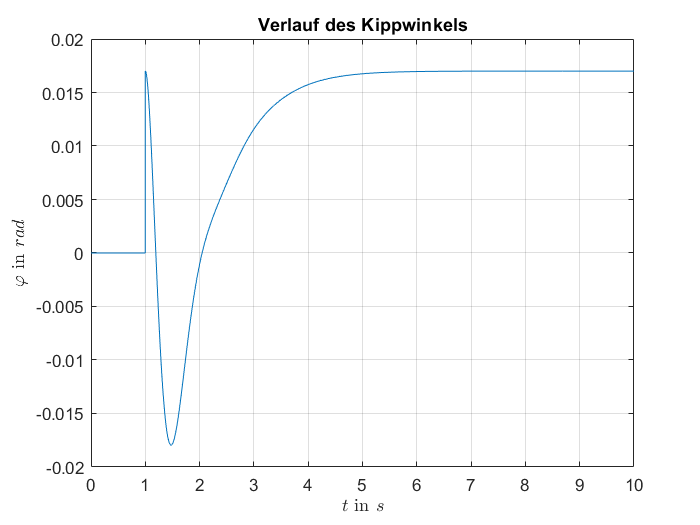


% Plotten des Verlaufs des Kippwinkels
figure()
plot(phi_c)
title("Verlauf des Kippwinkels")
xlabel("$t$ in $s$",'Interpreter','latex')
ylabel("$\varphi$  in  $rad$",'Interpreter','latex')
grid on

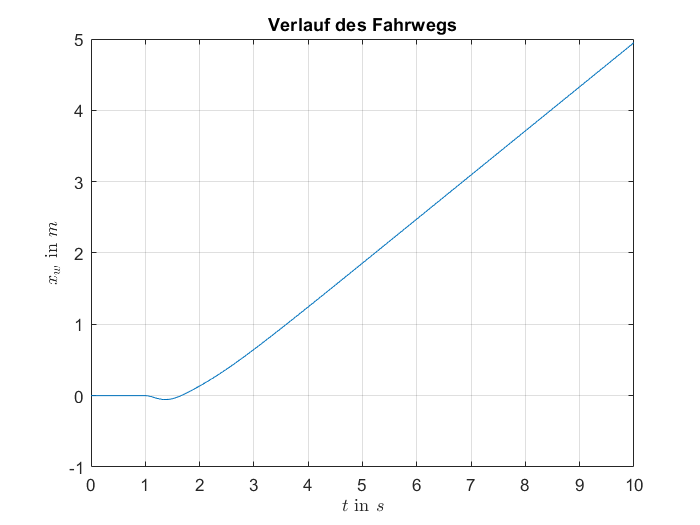

% Plotten des Verlaufs des Fahrwegs
figure()
plot(xw_c)
title("Verlauf des Fahrwegs")
xlabel("$t$ in $s$",'Interpreter','latex')
ylabel("$x_w$  in  $m$",'Interpreter','latex')
grid on

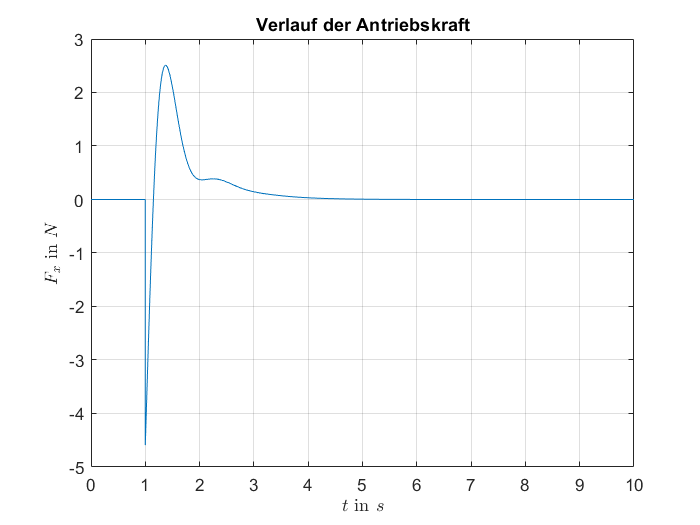

% Plotten des Verlaufs der Antriebskraft
figure()
plot(Fx_c)
title("Verlauf der Antriebskraft")
xlabel("$t$ in $s$",'Interpreter','latex')
ylabel("$F_x$  in  $N$",'Interpreter','latex')
grid on

### Vergleich der Regler

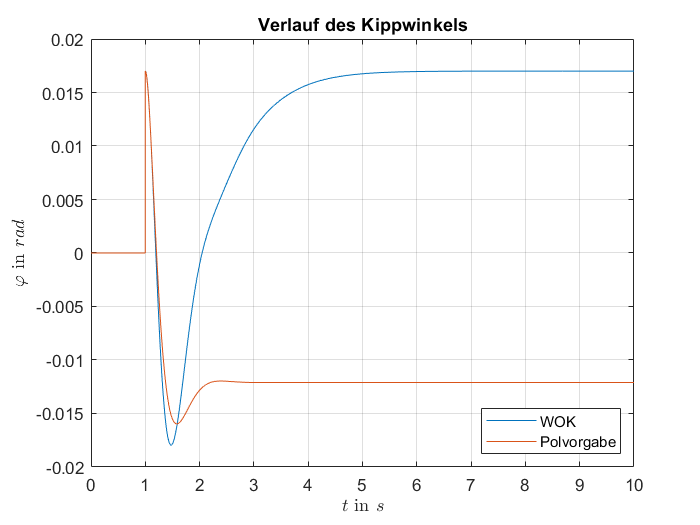

% Plotten des Verlaufs des Kippwinkels
figure()
plot(phi_c)
hold on
plot(phi_b)
legend("WOK","Polvorgabe","Location","southeast")
title("Verlauf des Kippwinkels")
xlabel("$t$ in $s$",'Interpreter','latex')
ylabel("$\varphi$  in  $rad$",'Interpreter','latex')
grid on

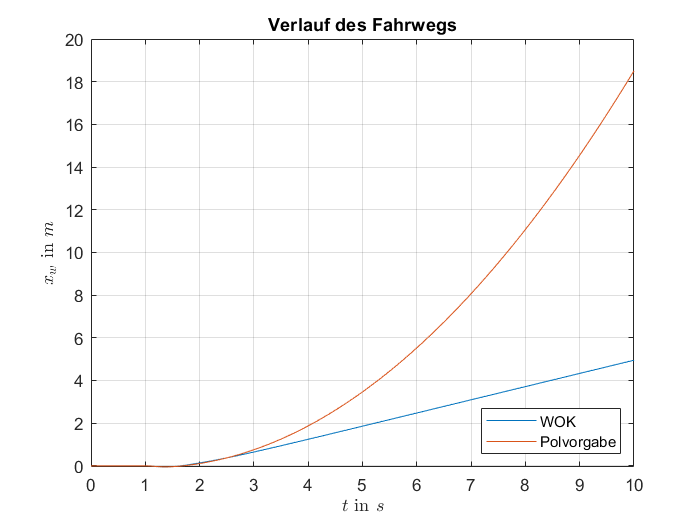

% Plotten des Verlaufs des Fahrwegs
figure()
plot(xw_c)
hold on
plot(xw_b)
legend("WOK","Polvorgabe","Location","southeast")
title("Verlauf des Fahrwegs")
xlabel("$t$ in $s$",'Interpreter','latex')
ylabel("$x_w$  in  $m$",'Interpreter','latex')
grid on

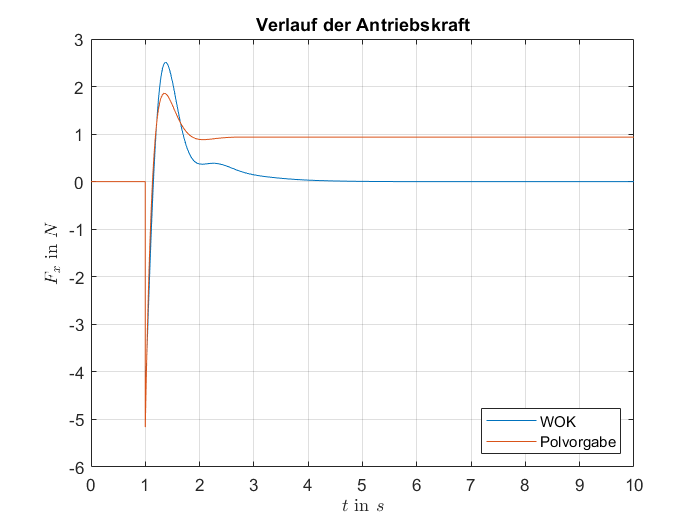

% Plotten des Verlaufs der Antriebskraft
figure()
plot(Fx_c)
hold on
plot(Fx_b)
legend("WOK","Polvorgabe","Location","southeast")
title("Verlauf der Antriebskraft")
xlabel("$t$ in $s$",'Interpreter','latex')
ylabel("$F_x$  in  $N$",'Interpreter','latex')
grid on